# projet numérique: parfum diffusion D Delta u(x,y) =f(x,y)

## param


clear
D=10^(-5);
h=10;%m pas de différences-finies

## A


A=zeros(25,25);
A1=diag(-4*ones(5,1))+diag(ones(4,1),-1)+diag(ones(4,1),1)

A1 =     -4     1     0     0     0
     1    -4     1     0     0
     0     1    -4     1     0
     0     0     1    -4     1
     0     0     0     1    -4


A2=diag(ones(5,1))

A2 =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


A3=zeros(5)

A3 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


A=[A1 A2 A3 A3 A3;
   A2 A1 A2 A3 A3;
   A3 A2 A1 A2 A3;
   A3 A3 A2 A1 A2;
   A3 A3 A3 A2 A1]

A =     -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -4     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     1    -4     1     0     0     0     1     0     0     0

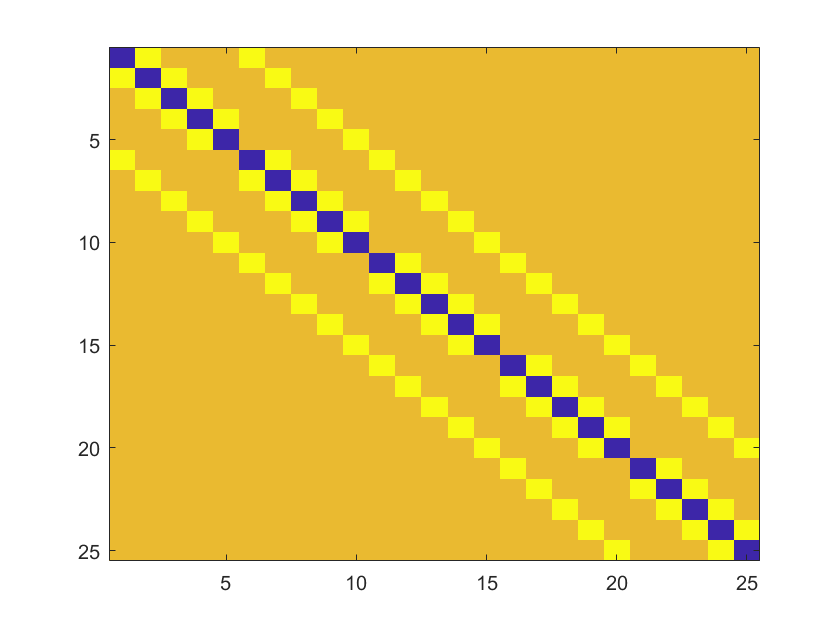

imagesc(A)

## b


b=zeros(25,1);% sources acoustiques
b(7)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((10^2)+(30^2))/2);% f7
b(8)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((20^2)+(30^2))/2); % f8
b(9)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((30^2)+(30^2))/2)% f9

b = 	1.0e+-210 *

         0
         0
         0
         0
         0
         0
   -0.2842
   -0.0000
         0
         0


b(12)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((20^2)+(10^2))/2);%f12
b(13)=-10

b =          0
         0
         0
         0
         0
         0
   -0.0000
   -0.0000
         0
         0


b(15)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((30^2)+(20^2))/2);%f14
b(17)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((10^2)+(10^2))/2);%f17
b(18)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((20^2)+(10^2))/2);%f18
b(19)= ((-h^2)/D)*(1/(2*pi)^0.5)*exp(-((30^2)+(10^2))/2);%f19



## sol

u=A\b;
% on va décomposer le vecteur u à matrice v
v=zeros(7);
for i=2:6
    v(i,2:6)=u(1+5*(i-2):5+5*(i-2));
end
v

v =          0         0         0         0         0         0         0
         0    0.2885    0.5769    0.7692    0.5769    0.2885         0
         0    0.5769    1.2500    1.9231    1.2500    0.5769         0
         0    0.7692    1.9231    4.4231    1.9231    0.7692         0
         0    0.5769    1.2500    1.9231    1.2500    0.5769         0
         0    0.2885    0.5769    0.7692    0.5769    0.2885         0
         0         0         0         0         0         0         0


v(1,:)=1;
v(7,:)=1;
v(:,1)=1;
v(:,7)=1;

## graphe


figure(1) % graphe standard
[xq,yq]=meshgrid(0:h:60,0:h:60)

xq =      0    10    20    30    40    50    60
     0    10    20    30    40    50    60
     0    10    20    30    40    50    60
     0    10    20    30    40    50    60
     0    10    20    30    40    50    60
     0    10    20    30    40    50    60
     0    10    20    30    40    50    60


yq =      0     0     0     0     0     0     0
    10    10    10    10    10    10    10
    20    20    20    20    20    20    20
    30    30    30    30    30    30    30
    40    40    40    40    40    40    40
    50    50    50    50    50    50    50
    60    60    60    60    60    60    60


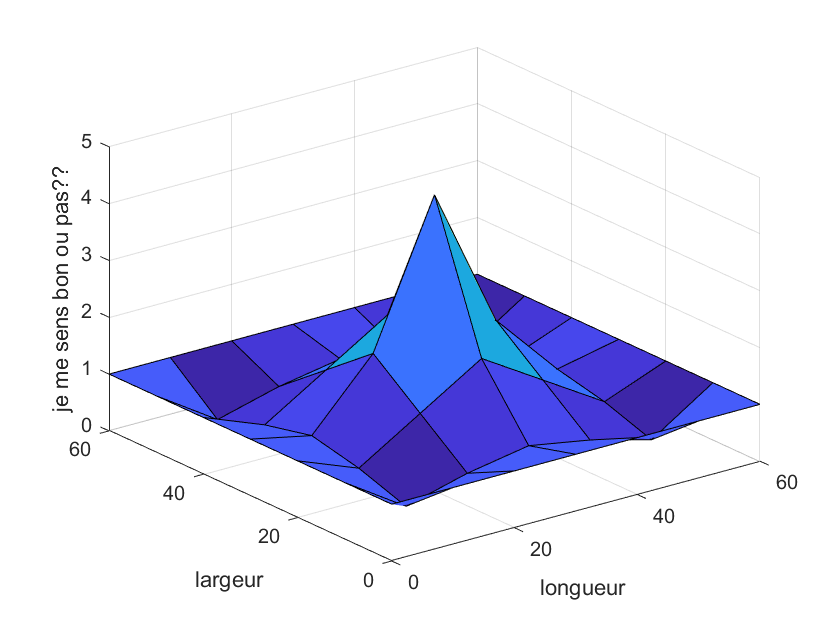

surf(xq,yq,v);
xlabel('longueur')
ylabel('largeur')
zlabel('je me sens bon ou pas??')

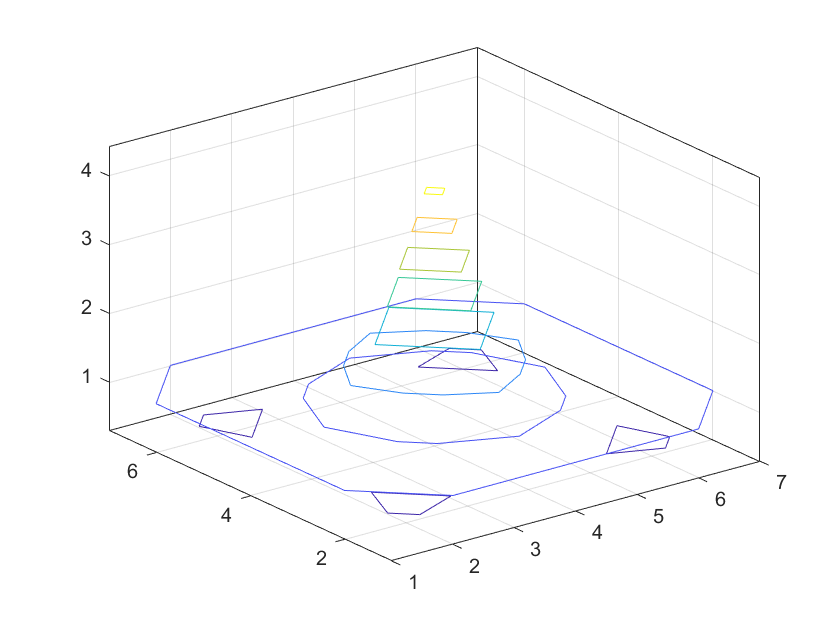

figure(2)
contour3(v); % contour

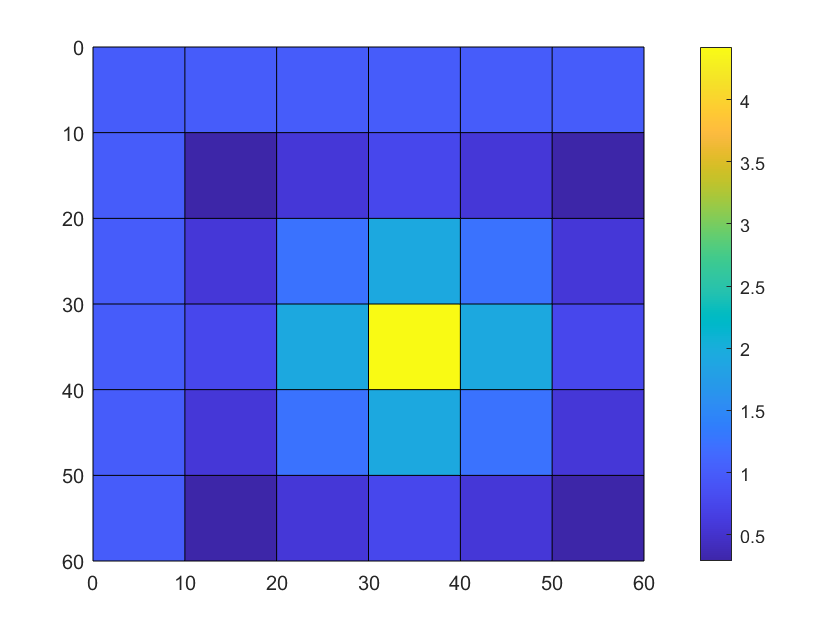


figure(3) % vue de dessus
surf(xq,yq,v);
view([90,90])
colorbar

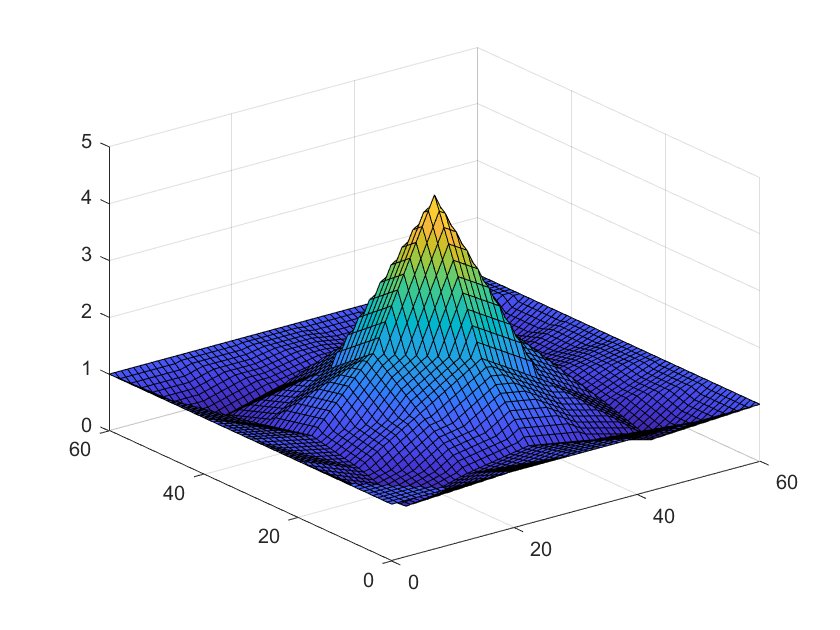


figure(4) % soften the graphic
[xqq,yqq]=meshgrid(0:1:60,0:1:60); %set the accuracy
vqq=griddata(xq,yq,v,xqq,yqq,'linear');
surf(xqq,yqq,vqq)

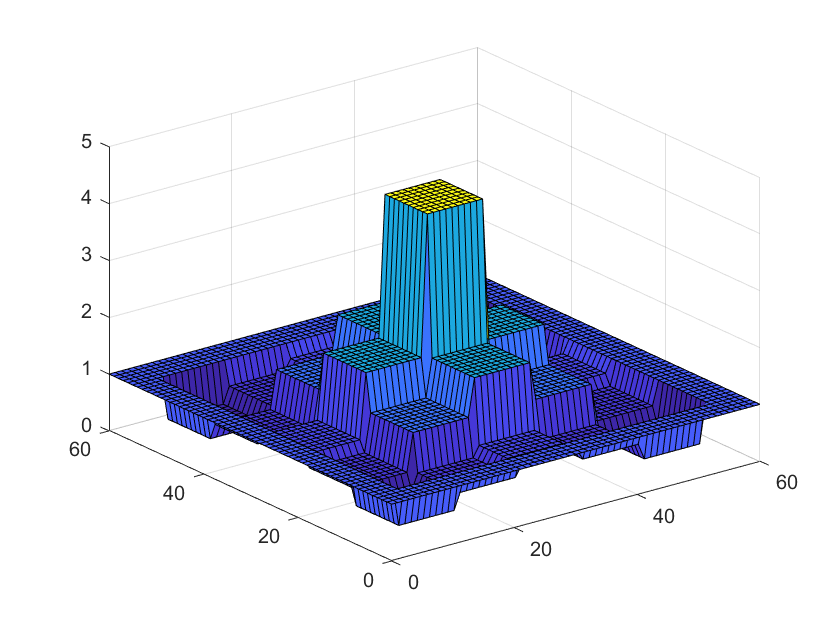


figure(5) % change the 'linear' to nearest, cubic or v4
% have fun :)
vqqq=griddata(xq,yq,v,xqq,yqq,'nearest'); % minecraft
surf(xqq,yqq,vqqq)